# **Procesamiento de Imagene Digitales**

**Taller 13.**

## Superposición de Procrustes

Teniendo en cuenta que la transformación afín conocida como *Superposición de Procrustes* comprende las transformaciones de *escalado, rotación y traslación*, segun la siguiente ecuación,

$\mathbf{T=SRX}$,

en donde $\mathbf{S}$ representa la matriz de escalado, $\mathbf{R}$ la de rotación y $\mathbf{X}$ la de traslación, en coordenadas homogeneas, se obtiene entonces la siguiente matriz de transformación $\mathbf{T$:

$T=\left\lbrack \begin{array}{ccc}
\alpha  & \gamma  & \lambda_1 \\
-\gamma  & \alpha  & \lambda_2 \\
0 & 0 & 1
\end{array}\right\rbrack$.

- Escriba las matrices de *escalado, rotación y traslación *en coordenadas homogeneas*. *

            $S_c =\left\lbrack \begin{array}{ccc}
s_c  & 0 & 0\\
0 & s_c  & 0\\
0 & 0 & 1
\end{array}\right\rbrack$,$R=\left\lbrack \begin{array}{ccc}
\textrm{Cos}\left(\theta \right) & \textrm{Sin}\left(\theta \right) & 0\\
-\textrm{Sin}\left(\theta \right) & \textrm{Cos}\left(\theta \right) & 0\\
0 & 0 & 1
\end{array}\right\rbrack$,$X=\left\lbrack \begin{array}{ccc}
1 & 0 & t_x \\
0 & 1 & t_y \\
0 & 0 & 1
\end{array}\right\rbrack$.

            
$$S_c \textrm{xR}\left\lbrack \begin{array}{ccc}
s_c *\textrm{Cos}\left(\theta \right) & s_c *\textrm{Sin}\left(\theta \right) & 0\\
-s_c *\textrm{Sin}\left(\theta \right) & s_c *\textrm{Cos}\left(\theta \right) & 0\\
0 & 0 & 1
\end{array}\right\rbrack$$


            
$$S_c \textrm{xRxX}=\left\lbrack \begin{array}{ccc}
s_c *\textrm{Cos}\left(\theta \right) & s_c *\textrm{Sin}\left(\theta \right) & \left.s_c {\left\lbrack t\right.}_x \textrm{Cos}\left(\theta \right)+t_y \textrm{Sin}\left(\theta \right)\right\rbrack \\
-s_c *\textrm{Sin}\left(\theta \right) & s_c *\textrm{Cos}\left(\theta \right) & s_c \left\lbrack t_y \textrm{Cos}\left(\theta \right)-t_x \textrm{Sin}\left(\theta \right)\right\rbrack \\
0 & 0 & 1
\end{array}\right\rbrack$$


- Realice la transformación afín y encuentre entonces las expresiones algebraicas para los terminos $\alpha$, $\gamma$, $\lambda_{1}$, y $\lambda2$.

              $\alpha$=$s_c *\textrm{Cos}\left(\theta \right)$;         $\gamma$=$s_c *\textrm{Sin}\left(\theta \right)$;        $\lambda_{1}$=$\left.s_c {\left\lbrack t\right.}_x \textrm{Cos}\left(\theta \right)+t_y \textrm{Sin}\left(\theta \right)\right\rbrack$

              $\lambda2$ = $s_c \left\lbrack t_y \textrm{Cos}\left(\theta \right)-t_x \textrm{Sin}\left(\theta \right)\right\rbrack$

## Ejercicio

Cargue el archivo de datos "`procrustes_star.mat". E`n una misma figura grafique los archivos `input_points` y `base_points` utilizando como marcadores diamantes negros (`‘kd’`) y asteristocos rojos (`‘r*’`), respectivamente. 

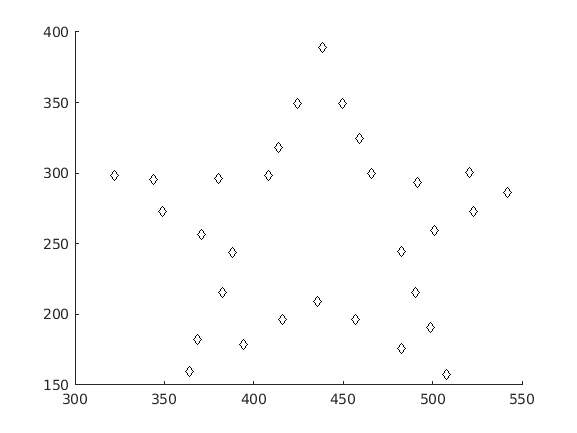

load('procrustes_star.mat');
figure(1);
hold on
scatter(base_points(:,1),base_points(:,2),'kd');
%scatter(input_points(:,1),input_points(:,2),'r*');
hold off

Teniendo en cuenta un factor de escalado $Sc=2.4941$, una rotación de $\theta=91.0390^{\circ}$, y una translación $(-566.7054, -103.4337)$, encuentre la respectiva matriz de transformación $\mathbf{T}$(en coordenadas homogeneas) para la respectiva ***Superposición de Procrustes.***

theta = 91.0390;
Sc = 2.4941;
T = [Sc*cos(theta) Sc*sin(theta) Sc*(-566.7054*cos(theta)-103.4337*sin(theta)); ...
    -Sc*sin(theta) Sc*cos(theta) Sc*(-103.4337*cos(theta)+566.7054*sin(theta)); ...
    0 0 1];

Una vez calculada la matriz de transformación, aplique la ***Superposición de Procrustes, ***$\mathbf{M=TS}$, en donde $\mathbf{S}$ corresponde a los datos del archivo `input_points. `En una nueva figura, grafique la superposición de los 2 archivos de coordenadas contenidas en "`procrustes_star.mat" `y las coordenadas transformadas $\mathbf{M}$,  utilizando como marcadores diamantes negros ('`kd'`) , asteristocos rojos ('`r*'`) y circulos verdes ('`g'`), respectivamente

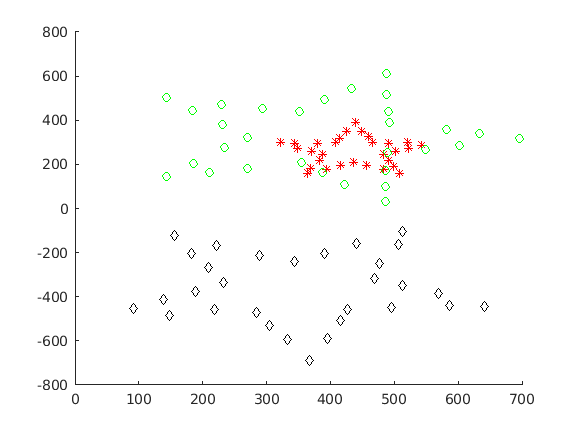

[M N] = size(input_points);
S = ones([M 3]);
S(:,1:2)=base_points;
M = (T*S')';
figure;
hold on
scatter(M(:,1),M(:,2),'kd');
scatter(base_points(:,1),base_points(:,2),'r*');
scatter(input_points(:,1),input_points(:,2),'go');
hold off